# doble_integracion_ofi

performs the integral double of a sampled signal with the optimally filtered integration (OFI method).

## Syntax

pos=doble_integracion_ofi(acc,freq)

## Description

`pos=dinteg_oci(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz with the the optimally filtered integration (OFI method). 

To reduce the low frequency acceleration noise the acceleration signal is high-pass-filtered, with a 2nd order Butterworth filter with an *f**c *Hz cut frequency, calculated from data of a given cycle with known equal initial and final velocities. After filtering, a first integration produced instantaneous velocity. The numerical method chosen to integrate the data is the Cavalieri–Simpson. If the so-estimated final velocity is close to the initial velocity, they are supposed as equal, and a weighted direct and reverse integration is applied, aimed to reduce the time drift in velocity. 

				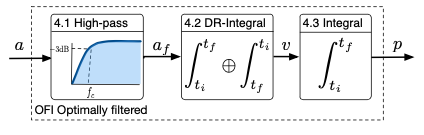

Notice that this method, contrary to the LRI and MSI methods, did not need a general assumption about the velocity at the end of the integration time 

More information: 

Köse, A.; Cereatti, A.; Della Croce, U. Bilateral step length estimation using a single inertial measurement 							unit attached to the pelvis. *J. NeuroEng. Rehabil. ***2012**, *9*, 9. 							

## Examples

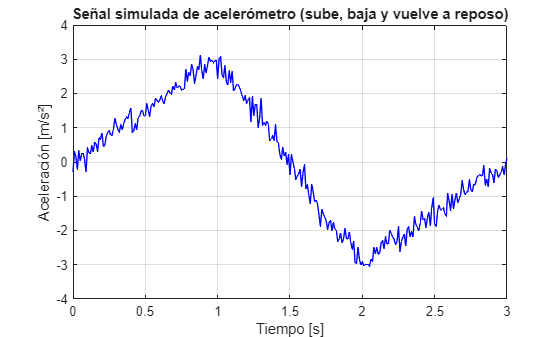

% Simulamos una señal de acelerómetro que sube, baja y vuelve a reposo con ruido
fs = 100;                     % Frecuencia de muestreo [Hz]
t = 0:1/fs:3;                 % Duración de 3 segundos
n = length(t);

% Creamos una forma de aceleración: subida, bajada, reposo
fase1 = linspace(0, 3, round(n/3));       % subida
fase2 = linspace(3, -3, round(n/3));      % bajada
fase3 = linspace(-3, 0, n - 2*round(n/3));% vuelta a reposo
acc_real = [fase1 fase2 fase3];           % concatenamos

% Añadimos ruido gaussiano para simular el sensor
ruido = 0.2*randn(1, n);
acc = (acc_real + ruido)';


% Visualizamos la señal simulada
figure
plot(t, acc, 'b')
xlabel('Tiempo [s]')
ylabel('Aceleración [m/s²]')
title('Señal simulada de acelerómetro (sube, baja y vuelve a reposo)')
grid on

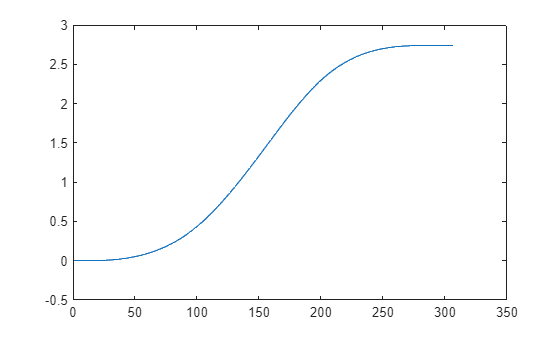


plot(doble_integracion_ofi(acc,100));